# Taller 3 punto 2

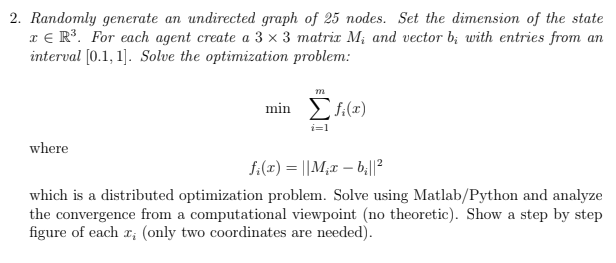

## **Optimización Distribuida Basada en Consenso**

En este experimento, se implementa un esquema de optimización distribuida basado en consenso en una red de **n = 25** nodos. Cada nodo mantiene un estado en un espacio tridimensional y busca minimizar una función de costo local mediante un algoritmo de actualización iterativa.

Para definir la conectividad entre los nodos, se genera una matriz de adyacencia aleatoria simétrica que representa un grafo no dirigido. Esta matriz es normalizada para garantizar que cada nodo tenga una contribución balanceada en la actualización de su estado.

Cada nodo posee una función de costo local definida por una matriz Mi y un vector bi que se generan aleatoriamente con valores en el intervalo [0.1, 1]. En cada iteración, los nodos actualizan sus estados combinando un promedio ponderado de los estados de sus vecinos y un término de descenso de gradiente basado en la función de costo local.

Tras 200 iteraciones, el estado de cada nodo converge hacia un valor cercano al consenso global, el cual se calcula como el promedio de los estados finales de todos los nodos. Se presentan gráficos que ilustran la evolución de los estados y la convergencia hacia el punto de consenso.

Los resultados muestran que la optimización distribuida basada en consenso es efectiva para minimizar las funciones de costo individuales de cada nodo, permitiendo alcanzar una solución común sin necesidad de una autoridad centralizada.

clc; clear; close all;
rng(42); % Para reproducibilidad

% Parámetros
n = 25; % Número de nodos
d = 3;  % Dimensión de x (en R^3)
alpha = 0.01; % Tasa de aprendizaje
max_iter = 200; % Número de iteraciones

% Crear un grafo aleatorio no dirigido (matriz de adyacencia simétrica)
A = randi([0, 1], n, n)

A =      0     1     1     1     0     0     1     0     1     0     0     1     0     1     1     0     0     1     1     1     1     0     1     1     0
     1     0     1     1     1     1     0     1     0     1     0     1     1     1     1     1     1     0     1     0     1     0     1     0     0
     1     1     1     0     0     1     0     0     0     0     1     1     1     1     1     0     1     1     0     1     0     0     1     1     0
     1     1     1     0     1     0     0     1     1     1     0     1     1     0     0     1     1     0     1     1     1     0     1     0     0
     0     0     1     0     1     1     1     0     1     1     0     1     1     0     0     0     0     0     0     1     1     1     1     0     0
     0     1     1     1     0     0     0     0     0     1     1     1     1     0     1     0     1     0     0     1     0     1     0     0     0
     0     0     0     1     0     0     1     0     0     1     1     0     1     1     0

A = triu(A, 1); 
A = A + A'; % Hacerlo simétrico (no dirigido)
A = A - diag(diag(A)); % Asegurar que no haya auto-conexiones

% Normalizar A para que sea doblemente estocástica
A = A ./ (sum(A, 2))

A =          0    0.0714    0.0714    0.0714         0         0    0.0714         0    0.0714         0         0    0.0714         0    0.0714    0.0714         0         0    0.0714    0.0714    0.0714    0.0714         0    0.0714    0.0714         0
    0.0625         0    0.0625    0.0625    0.0625    0.0625         0    0.0625         0    0.0625         0    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625         0    0.0625         0    0.0625         0    0.0625         0         0
    0.0769    0.0769         0         0         0    0.0769         0         0         0         0    0.0769    0.0769    0.0769    0.0769    0.0769         0    0.0769    0.0769         0    0.0769         0         0    0.0769    0.0769         0
    0.0714    0.0714         0         0    0.0714         0         0    0.0714    0.0714    0.0714         0    0.0714    0.0714         0         0    0.0714    0.0714         0    0.0714    0.0714    0.0714         0    0.0714         0   


%% Inicializar estados x_i en R^3
x = rand(d, n, max_iter); % Estados de los nodos en cada iteración

% Crear matrices M_i y vectores b_i para cada agente
M = zeros(d, d, n); % Matrices M_i
b = zeros(d, n); % Vectores b_i
for i = 1:n
    M(:, :, i) = 0.1 + 0.9 * rand(d, d) % Entradas en [0.1, 1]
    b(:, i) = 0.1 + 0.9 * rand(d, 1) % Entradas en [0.1, 1]
end

M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,3) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,4) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,5) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,6) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,7) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,8) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,9) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,10) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,11) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,12) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,13) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,14) =

     0     0     0
 

b =     0.4665         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1235         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6088         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,4) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,5) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,6) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,7) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,8) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,9) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,10) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,11) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,12) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,13) =

     0     0     0
     0     0     0
     0     0     0

b =     0.4665    0.8283         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1235    0.8386         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6088    0.2757         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,5) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,6) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,7) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,8) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,9) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,10) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,11) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,12) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,13) =

     0     0     0
 

b =     0.4665    0.8283    0.3203         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1235    0.8386    0.4387         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6088    0.2757    0.3710         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,6) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,7) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,8) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,9) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,10) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,11) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,12) =

     0     0     0
     0     0     0
     0     0     0

b =     0.4665    0.8283    0.3203    0.6547         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,7) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,8) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,9) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,10) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,11) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,12) =

     0     0     0
 

b =     0.4665    0.8283    0.3203    0.6547    0.1033         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,8) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,9) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,10) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,11) =

     0     0     0
     0     0     0
     0     0     0

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,9) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,10) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,11) =

     0     0     0
 

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

     0     0     0
     0     0     0
     0     0     0


M(:,:,10) =

     0     0     0
     0     0     0
     0     0     0

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

     0     0     0
 

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

    0.4385    0.3314

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832    0.9260         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059    0.7001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304    0.5244         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

    0.4385    0.3314

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832    0.9260    0.9185         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059    0.7001    0.8532         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304    0.5244    0.6985         0         0         0         0         0         0         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

    0.4385    0.3314

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832    0.9260    0.9185    0.6688         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059    0.7001    0.8532    0.6542         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304    0.5244    0.6985    0.5957         0         0         0         0         0         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

    0.4385    0.3314

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832    0.9260    0.9185    0.6688    0.1299         0         0         0         0         0         0         0         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059    0.7001    0.8532    0.6542    0.9971         0         0         0         0         0         0         0         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304    0.5244    0.6985    0.5957    0.1891         0         0         0         0         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

    0.4385    0.3314

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832    0.9260    0.9185    0.6688    0.1299    0.8188         0         0         0         0         0         0         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059    0.7001    0.8532    0.6542    0.9971    0.5127         0         0         0         0         0         0         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304    0.5244    0.6985    0.5957    0.1891    0.2798         0         0         0         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

    0.4385    0.3314

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832    0.9260    0.9185    0.6688    0.1299    0.8188    0.6119         0         0         0         0         0         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059    0.7001    0.8532    0.6542    0.9971    0.5127    0.5065         0         0         0         0         0         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304    0.5244    0.6985    0.5957    0.1891    0.2798    0.4915         0         0         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

    0.4385    0.3314

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832    0.9260    0.9185    0.6688    0.1299    0.8188    0.6119    0.4355         0         0         0         0         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059    0.7001    0.8532    0.6542    0.9971    0.5127    0.5065    0.7117         0         0         0         0         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304    0.5244    0.6985    0.5957    0.1891    0.2798    0.4915    0.7417         0         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

    0.4385    0.3314

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832    0.9260    0.9185    0.6688    0.1299    0.8188    0.6119    0.4355    0.3679         0         0         0         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059    0.7001    0.8532    0.6542    0.9971    0.5127    0.5065    0.7117    0.6047         0         0         0         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304    0.5244    0.6985    0.5957    0.1891    0.2798    0.4915    0.7417    0.3322         0         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

    0.4385    0.3314

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832    0.9260    0.9185    0.6688    0.1299    0.8188    0.6119    0.4355    0.3679    0.9473         0         0         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059    0.7001    0.8532    0.6542    0.9971    0.5127    0.5065    0.7117    0.6047    0.9027         0         0         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304    0.5244    0.6985    0.5957    0.1891    0.2798    0.4915    0.7417    0.3322    0.6188         0         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

    0.4385    0.3314

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832    0.9260    0.9185    0.6688    0.1299    0.8188    0.6119    0.4355    0.3679    0.9473    0.2592         0         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059    0.7001    0.8532    0.6542    0.9971    0.5127    0.5065    0.7117    0.6047    0.9027    0.6959         0         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304    0.5244    0.6985    0.5957    0.1891    0.2798    0.4915    0.7417    0.3322    0.6188    0.2422         0         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

    0.4385    0.3314

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832    0.9260    0.9185    0.6688    0.1299    0.8188    0.6119    0.4355    0.3679    0.9473    0.2592    0.6293         0         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059    0.7001    0.8532    0.6542    0.9971    0.5127    0.5065    0.7117    0.6047    0.9027    0.6959    0.3309         0         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304    0.5244    0.6985    0.5957    0.1891    0.2798    0.4915    0.7417    0.3322    0.6188    0.2422    0.6073         0         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

    0.4385    0.3314

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832    0.9260    0.9185    0.6688    0.1299    0.8188    0.6119    0.4355    0.3679    0.9473    0.2592    0.6293    0.5134         0         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059    0.7001    0.8532    0.6542    0.9971    0.5127    0.5065    0.7117    0.6047    0.9027    0.6959    0.3309    0.9169         0         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304    0.5244    0.6985    0.5957    0.1891    0.2798    0.4915    0.7417    0.3322    0.6188    0.2422    0.6073    0.2511         0         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

    0.4385    0.3314

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832    0.9260    0.9185    0.6688    0.1299    0.8188    0.6119    0.4355    0.3679    0.9473    0.2592    0.6293    0.5134    0.7188         0         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059    0.7001    0.8532    0.6542    0.9971    0.5127    0.5065    0.7117    0.6047    0.9027    0.6959    0.3309    0.9169    0.4143         0         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304    0.5244    0.6985    0.5957    0.1891    0.2798    0.4915    0.7417    0.3322    0.6188    0.2422    0.6073    0.2511    0.5606         0         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

    0.4385    0.3314

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832    0.9260    0.9185    0.6688    0.1299    0.8188    0.6119    0.4355    0.3679    0.9473    0.2592    0.6293    0.5134    0.7188    0.1370         0         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059    0.7001    0.8532    0.6542    0.9971    0.5127    0.5065    0.7117    0.6047    0.9027    0.6959    0.3309    0.9169    0.4143    0.1644         0         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304    0.5244    0.6985    0.5957    0.1891    0.2798    0.4915    0.7417    0.3322    0.6188    0.2422    0.6073    0.2511    0.5606    0.3925         0         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

    0.4385    0.3314

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832    0.9260    0.9185    0.6688    0.1299    0.8188    0.6119    0.4355    0.3679    0.9473    0.2592    0.6293    0.5134    0.7188    0.1370    0.9397         0
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059    0.7001    0.8532    0.6542    0.9971    0.5127    0.5065    0.7117    0.6047    0.9027    0.6959    0.3309    0.9169    0.4143    0.1644    0.7801         0
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304    0.5244    0.6985    0.5957    0.1891    0.2798    0.4915    0.7417    0.3322    0.6188    0.2422    0.6073    0.2511    0.5606    0.3925    0.8107         0


M = M(:,:,1) =

    0.3915    0.8954    0.5182
    0.6479    0.1976    0.9799
    0.8886    0.4855    0.7102


M(:,:,2) =

    0.1865    0.5145    0.3596
    0.8510    0.4863    0.3241
    0.7773    0.9076    0.9453


M(:,:,3) =

    0.2290    0.7968    0.3267
    0.1234    0.3160    0.4558
    0.3133    0.7562    0.9848


M(:,:,4) =

    0.1987    0.7254    0.1290
    0.5409    0.8358    0.6570
    0.4408    0.5898    0.1499


M(:,:,5) =

    0.8374    0.3746    0.3886
    0.9200    0.6280    0.8380
    0.8318    0.9233    0.1085


M(:,:,6) =

    0.8101    0.3088    0.7140
    0.9370    0.9134    0.5774
    0.2061    0.2595    0.1749


M(:,:,7) =

    0.7368    0.3688    0.1257
    0.6597    0.2073    0.2900
    0.5464    0.4682    0.4892


M(:,:,8) =

    0.5947    0.1894    0.8941
    0.1703    0.8694    0.1177
    0.9488    0.1003    0.7820


M(:,:,9) =

    0.1638    0.9299    0.7507
    0.7908    0.1459    0.4539
    0.1641    0.5314    0.2955


M(:,:,10) =

    0.4385    0.3314

b =     0.4665    0.8283    0.3203    0.6547    0.1033    0.3567    0.4767    0.4255    0.7832    0.9260    0.9185    0.6688    0.1299    0.8188    0.6119    0.4355    0.3679    0.9473    0.2592    0.6293    0.5134    0.7188    0.1370    0.9397    0.3143
    0.1235    0.8386    0.4387    0.7165    0.7837    0.5683    0.1399    0.7644    0.8059    0.7001    0.8532    0.6542    0.9971    0.5127    0.5065    0.7117    0.6047    0.9027    0.6959    0.3309    0.9169    0.4143    0.1644    0.7801    0.4815
    0.6088    0.2757    0.3710    0.2780    0.7853    0.8671    0.6302    0.4616    0.9304    0.5244    0.6985    0.5957    0.1891    0.2798    0.4915    0.7417    0.3322    0.6188    0.2422    0.6073    0.2511    0.5606    0.3925    0.8107    0.1132



% Algoritmo de optimización distribuida
for t = 1:max_iter-1
    for i = 1:n
        % Obtener los vecinos del nodo i
        neighbors = find(A(i, :) > 0);
        
        % Calcular el promedio ponderado de los estados de los vecinos
        weighted_sum = zeros(d, 1);
        for j = neighbors
            weighted_sum = weighted_sum + A(i, j) * x(:, j, t);
        end
        
        % Calcular el gradiente de la función de costo local
        grad = 2 * M(:, :, i)' * (M(:, :, i) * x(:, i, t) - b(:, i));
        
        % Actualizar el estado del nodo i
        x(:, i, t+1) = weighted_sum - alpha * grad;
    end
end

% Calcular el valor de consenso (promedio de los estados finales)
consensus_value = mean(x(:, :, end), 2); % Promedio sobre todos los nodos

% Mostrar el valor de consenso
disp('El valor de consenso es:');

El valor de consenso es:


disp(consensus_value);

    0.2920
    0.4100
    0.2778



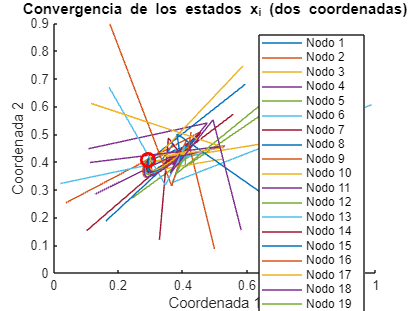


% Graficar la convergencia de los estados (solo dos coordenadas)
figure;
hold on;
for i = 1:n
    plot(squeeze(x(1, i, :)), squeeze(x(2, i, :)), 'DisplayName', ['Nodo ' num2str(i)]);
end

% Dibujar el punto de consenso
plot(consensus_value(1), consensus_value(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Consenso');

xlabel('Coordenada 1');
ylabel('Coordenada 2');
legend show;
title('Convergencia de los estados x_i (dos coordenadas)');
hold off;

Se gráfica para un solo nodo y ver su trayectoria más facilmente.

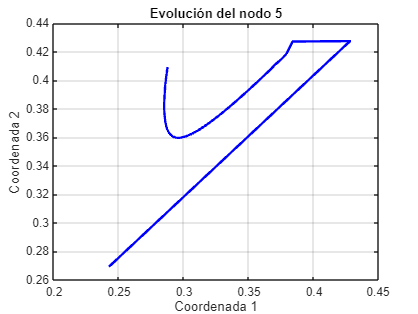

% Graficar la evolución de un nodo específico (por ejemplo, el nodo 1)
nodo_especifico = 5; % Seleccionar el nodo 1
figure;
plot(squeeze(x(1, nodo_especifico, :)), squeeze(x(2, nodo_especifico, :)), 'b-', 'LineWidth', 2);
xlabel('Coordenada 1');
ylabel('Coordenada 2');
title(['Evolución del nodo ' num2str(nodo_especifico)]);
grid on;

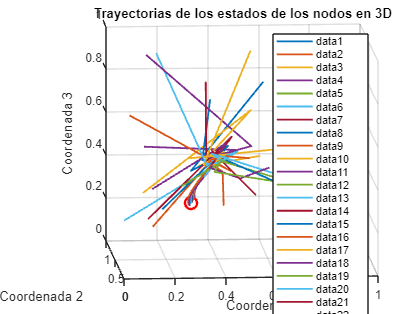

% Graficar la evolución de los estados de los nodos en 3D

figure;
hold on;
grid on;
xlabel('Coordenada 1');
ylabel('Coordenada 2');
zlabel('Coordenada 3');
title('Trayectorias de los estados de los nodos en 3D');

for i = 1:n
    plot3(squeeze(x(1, i, :)), squeeze(x(2, i, :)), squeeze(x(3, i, :)), 'LineWidth', 1.5);
end

% Dibujar el punto de consenso
plot3(consensus_value(1), consensus_value(2), consensus_value(3), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Consenso');

legend('show');
view(3); % Establecer la vista en 3D
hold off;